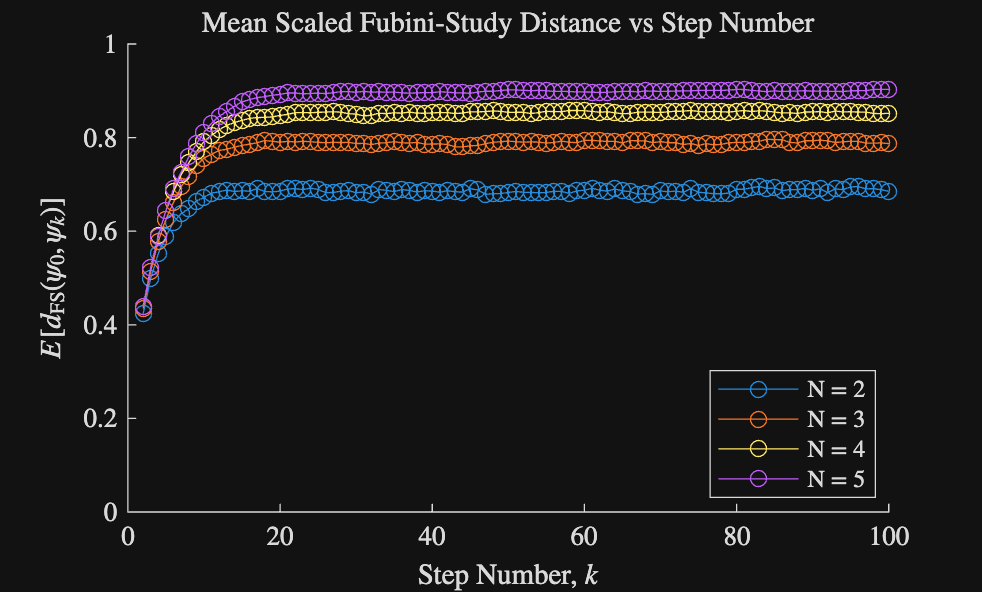

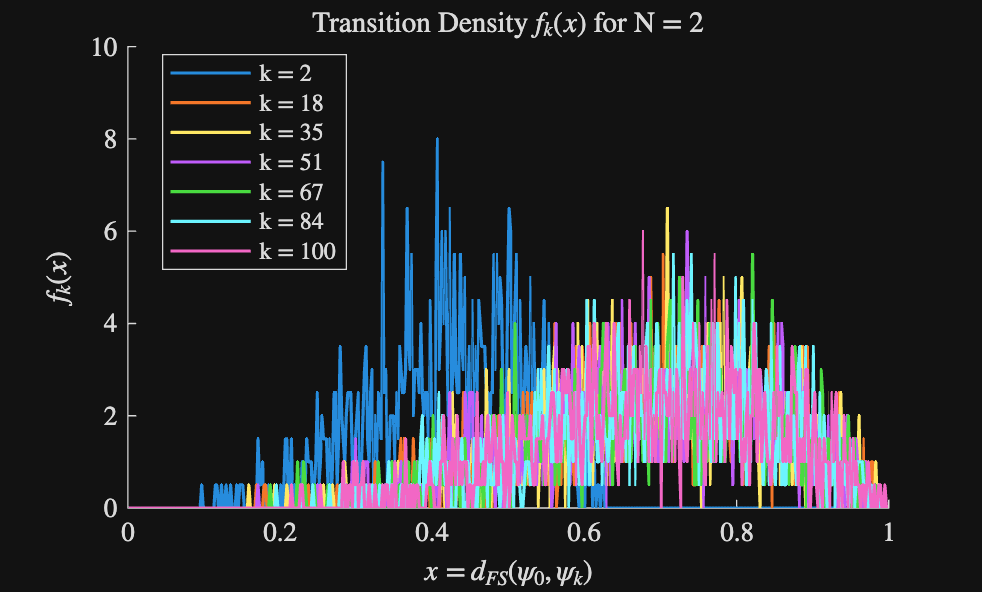

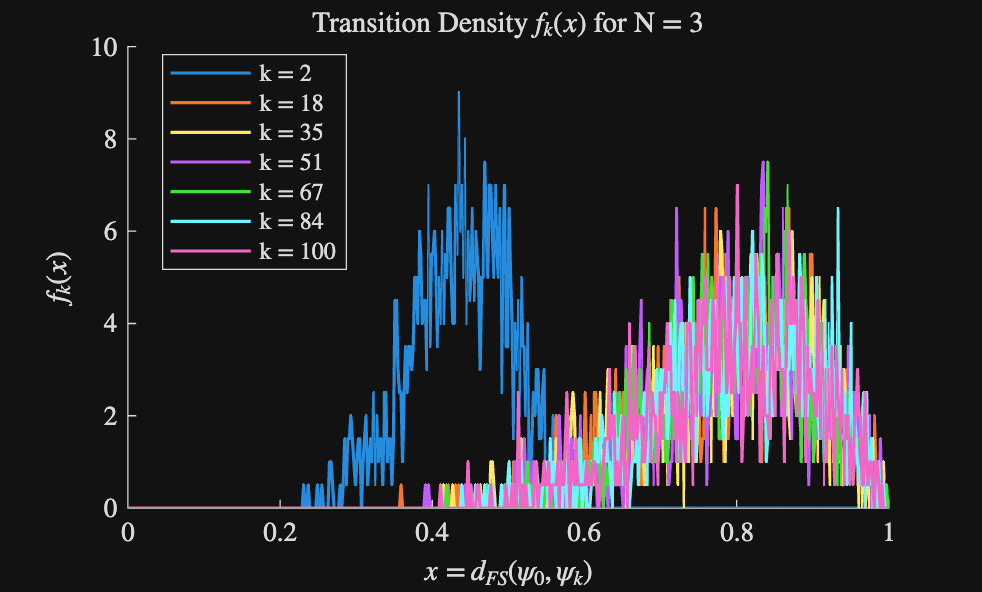

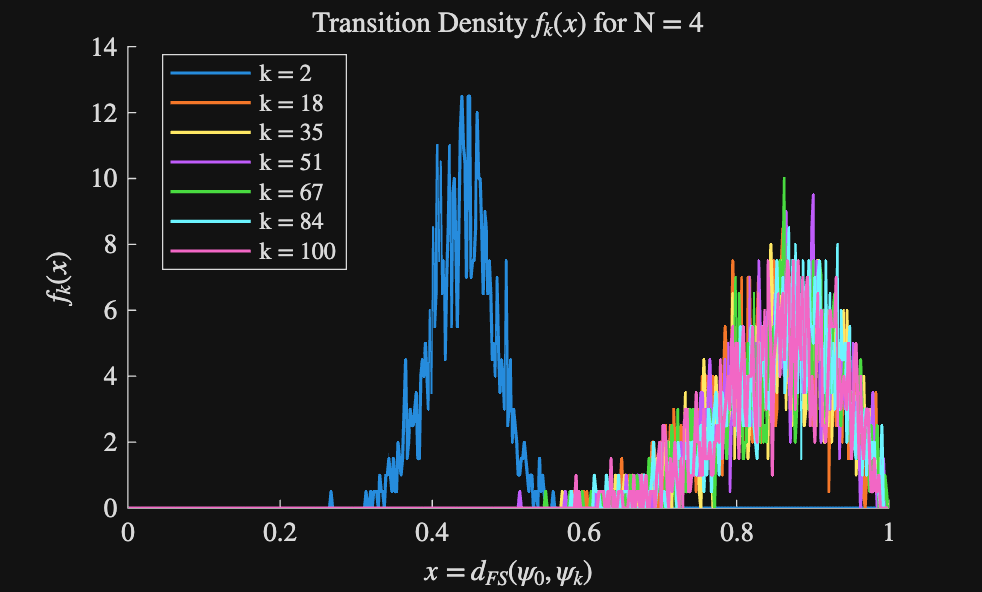

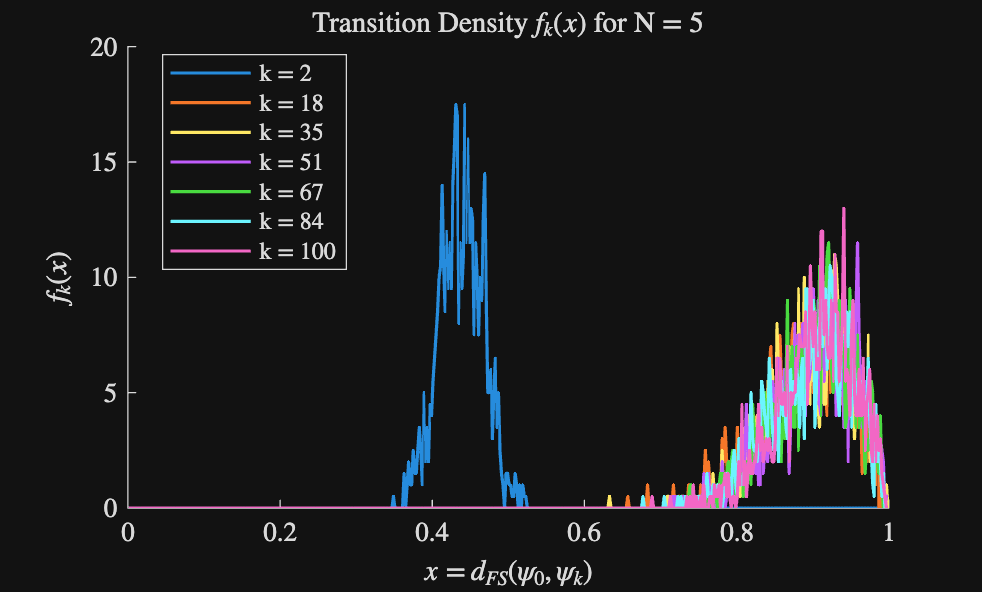

set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Number_of_Qubits = 2:1:7;

Number_of_Steps = 2:50;

Number_of_Walks = 25000;
Step_Size = 0.3;

Random_Walk_Algorithm_Calculator(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size);


function Random_Walk_Algorithm_Calculator(Nvals, Number_of_Steps, Number_of_Walks, Step_Size)

    Steps_Sweep = normalize_steps_input(Number_of_Steps);

    Qubit_Number         = numel(Nvals);
    Required_Step_Counts = numel(Steps_Sweep);

    % ---------------------------------------------------------------------
    % Histogram configuration (Plotting - Transition Prob. Densities)
    % ---------------------------------------------------------------------
    Num_Bins    = 500;
    Bin_Edges   = linspace(0, 1, Num_Bins+1);
    Bin_Centers = 0.5*(Bin_Edges(1:end-1) + Bin_Edges(2:end));

    Mean_Distances         = zeros(Qubit_Number, Required_Step_Counts);
    RWA_Samples_Each_Qubit = cell(Qubit_Number, 1);

    for Current_Qubit_Number = 1:Qubit_Number

        [RWA, RWA_Samples] = Random_Walk_Algorithm(Current_Qubit_Number, Steps_Sweep, Number_of_Walks, Step_Size);

        Mean_Distances(Current_Qubit_Number, :)        = RWA;
        RWA_Samples_Each_Qubit{Current_Qubit_Number}   = RWA_Samples;
    end

    % ---------------------------------------------------------------------
    % Figure 1: Mean distance vs step number
    % ---------------------------------------------------------------------

    figure('Name','Mean Fubini–Study Distance vs Step Number');
    hold on

    for Current_Qubit_Number = 1:Qubit_Number
        plot(Steps_Sweep, Mean_Distances(Current_Qubit_Number, :), 'o-');
    end

    ylim([0, 1]);
    xlabel('Step Number, $k$');
    ylabel('$E[d_{\mathrm{FS}}(\psi_0,\psi_k)]$');
    title(sprintf('Mean Scaled Fubini-Study Distance vs Step Number'));
    legend(arrayfun(@(N) sprintf('N = %d', N), Nvals, 'UniformOutput', false), 'Location', 'best');
    hold off;

    % ---------------------------------------------------------------------
    % Figure 2: 
    % ---------------------------------------------------------------------

    Number_of_Plotted_Curves = min(7, numel(Steps_Sweep));
    Selected_Steps = unique(round(linspace(Steps_Sweep(1), Steps_Sweep(end), Number_of_Plotted_Curves)));

    Selected_Steps = unique([Steps_Sweep(1), Selected_Steps]);
    Selected_Steps = Selected_Steps(Selected_Steps >= Steps_Sweep(1) & Selected_Steps <= Steps_Sweep(end));

    Selected_Indices = zeros(size(Selected_Steps));
    
    % index mapping for step size inputs

    for Step_Index = 1:numel(Selected_Steps)

        step = find(Steps_Sweep == Selected_Steps(Step_Index), 1);
        Selected_Indices(Step_Index) = step;
    end

    Selected_Steps = Steps_Sweep(Selected_Indices); 

    for Current_Qubit_Number = 1:Qubit_Number
        Number_Qubits = Nvals(Current_Qubit_Number);
        RWA_Samples = RWA_Samples_Each_Qubit{Current_Qubit_Number};

        figure('Name',sprintf('Transition Density Curves (N=%d)', Number_Qubits));
        hold on

        for Step_Index = 1:numel(Selected_Indices)
            step     = Selected_Indices(Step_Index);
            Samples = RWA_Samples(:, step);
            Counts  = histcounts(Samples, Bin_Edges, 'Normalization', 'pdf');
            plot(Bin_Centers, Counts, 'LineWidth', 1.2);
        end

        xlabel('$x = \,d_{FS}(\psi_0,\psi_k)$');
        ylabel('$f_k(x)$');
        title(sprintf('Transition Density $f_k(x)$ for N = %d', Number_Qubits));
        legend(arrayfun(@(m) sprintf('k = %d', m), Selected_Steps, 'UniformOutput', false), 'Location', 'best');
        xlim([0, 1]);
        hold off;
    end

    % ---------------------------------------------------------------------
    % Figure 3: 
    % ---------------------------------------------------------------------

    % for kk = 1:Required_Step_Counts
    %     k_val = Steps_Sweep(kk);
    %
    %     figure('Name',sprintf('Transition Density vs N (k=%d)', k_val));
    %     hold on
    %     for q = 1:Qubit_Number
    %         Samples = RWA_Samples_Each_Qubit{q}(:, kk);
    %         Counts  = histcounts(Samples, Bin_Edges, 'Normalization', 'pdf');
    %         plot(Bin_Centers, Counts, 'LineWidth', 1.2);
    %     end
    %     xlabel(sprintf('$x = (2/\\pi)\\,d_{FS}(\\psi_0,\\psi_{k})$,\\; k = %d', k_val));
    %     ylabel('$f_{k}(x)$');
    %     title(sprintf('Transition Density Comparison Across N at k = %d (Step Size = %.3f rad)', k_val, Step_Size));
    %     legend(arrayfun(@(N) sprintf('N = %d', N), Nvals, 'UniformOutput', false), 'Location', 'best');
    %     xlim([0, 1]);
    %     hold off;
    % end

end

% =========================================================================
% Step input normalizer (keeps user inputs simple)
% =========================================================================
function Steps_Sweep = normalize_steps_input(Number_of_Steps)

    if isempty(Number_of_Steps)
        error('Number_of_Steps is empty. Provide a scalar max step or a vector of steps.');
    end

    if isscalar(Number_of_Steps)
        MaxSteps = Number_of_Steps;
        if ~(isfinite(MaxSteps) && MaxSteps == floor(MaxSteps) && MaxSteps >= 1)
            error('If Number_of_Steps is scalar, it must be an integer >= 1.');
        end
        Steps_Sweep = 1:MaxSteps;
    else
        Steps_Sweep = Number_of_Steps(:).';
        if any(~isfinite(Steps_Sweep)) || any(Steps_Sweep ~= floor(Steps_Sweep)) || any(Steps_Sweep < 1)
            error('If Number_of_Steps is a vector, it must contain integers >= 1.');
        end
        Steps_Sweep = unique(Steps_Sweep, 'stable');
    end

end

function [RWA, RWA_Samples] = Random_Walk_Algorithm(Number_of_Qubits, Steps_Sweep, Number_of_Walks, Step_Size)

    Dimensions = 2^Number_of_Qubits;
    Maximum_Number_Steps   = max(Steps_Sweep);
    Step_Count  = numel(Steps_Sweep);

    Pole_Vector       = zeros(Dimensions, 1);
    Pole_Vector(1, 1) = 1;

    Component_Volume = Number_of_Walks * Maximum_Number_Steps;
    Vector_Database  = randn(Dimensions, Component_Volume) + 1i*randn(Dimensions, Component_Volume);

    RWA_Samples = zeros(Number_of_Walks, Step_Count);

    for i = 1:Number_of_Walks

        Walk_Vector_Block_Offset = (i-1)*Maximum_Number_Steps;
        Step_Sweep_Index = 0;

        for Step_Index = Steps_Sweep
            Step_Sweep_Index = Step_Sweep_Index + 1;

            Vectors       = zeros(Dimensions, Step_Index+1);
            Vectors(:, 1) = Pole_Vector;

            for k = 1:Step_Index

                Selected_Vector = Vector_Database(:, Walk_Vector_Block_Offset + k);

                Orthogonal_Vector = Selected_Vector - dot(Vectors(:, k), Selected_Vector) * Vectors(:, k);

                Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);

                Vectors(:, k+1) = (cos(Step_Size) * Vectors(:, k)) + (sin(Step_Size) * Normalized_Vector);
            end

            RWA_Samples(i, Step_Sweep_Index) = (2/pi) * Fubini_Study_Distance(Vectors(:, 1), Vectors(:, Step_Index+1));
        end
    end

    RWA = abs(mean(RWA_Samples, 1));

end

function FBS = Fubini_Study_Distance(Vector_1, Vector_2)
    FBS = acos(abs(dot(Vector_1, Vector_2)));
end